load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV_array=table2array(HCV);

# Remove outliers

[cdata,tf]=rmoutliers(HCV_array(:,[1,3,11:end]))

cdata =           46          29       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          49          33        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301          10           3
          58          22       11785     3882456          15      131228          66         104         121          96          65          73         114          29     1157452     1086852           5           5           5           4           4
          42          26       11620     4747333          12      177261          78          57         113         118         107          84          80          28      325694     1034008      275095      214566      635157     

tf = 1385×1 logical array
   1
   0
   1
   0
   1
   0
   0
   0
   0
   0


for i=1:1385
    if tf(i)==1
        HCV_array(i,:)=[];
    end
end
cdatat=array2table(cdata,'VariableNames',HCV.Properties.VariableNames([1,3,11:end]))

cdatat = 1381×21 table
    Age    BMI     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ___    _____    __________    ___    __________    ____    ____    ____    _____    _____    _____    _____    ___

HCV_array

HCV_array =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829           4           4
          59           1          32           1           1           2           1           2           2           2        3661     4606375          11      187684          99         104          67          48         120          94          90          30      660410      738756  

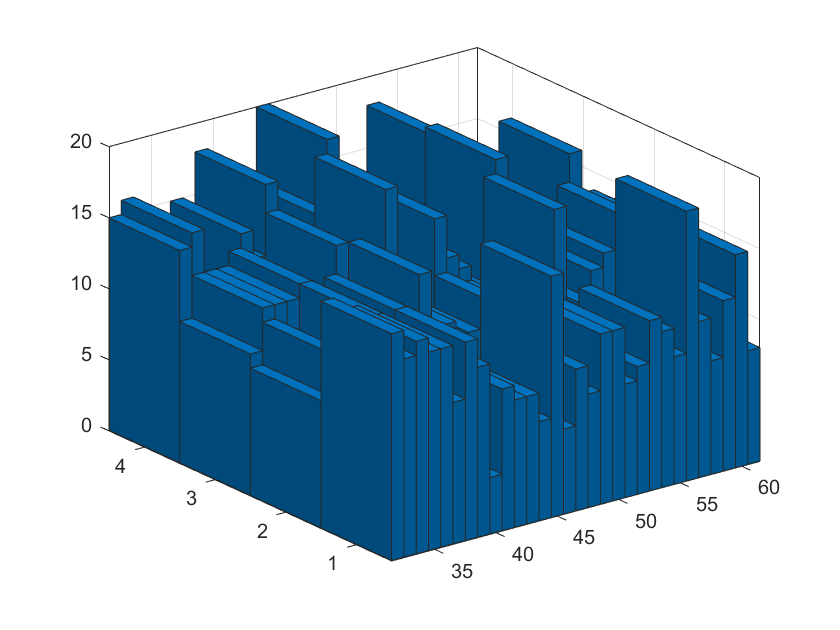

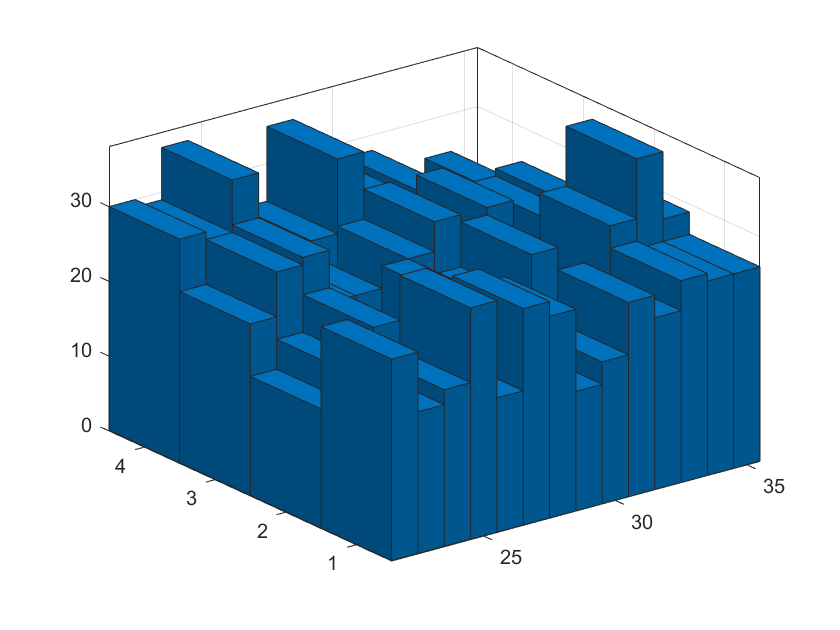

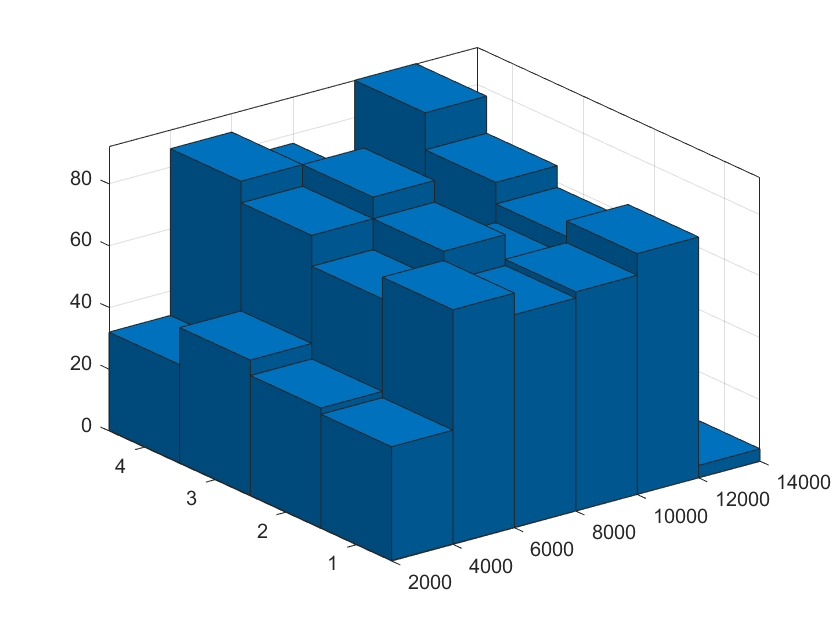

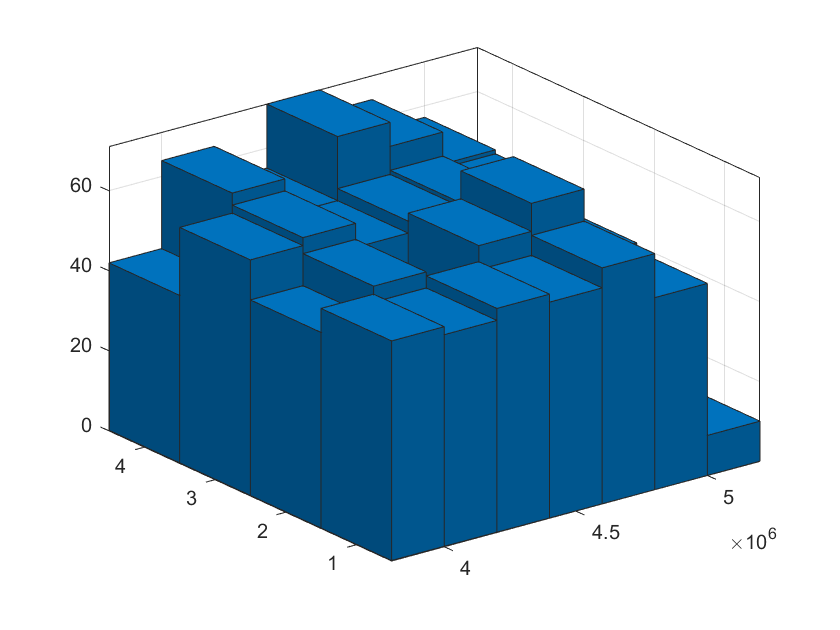

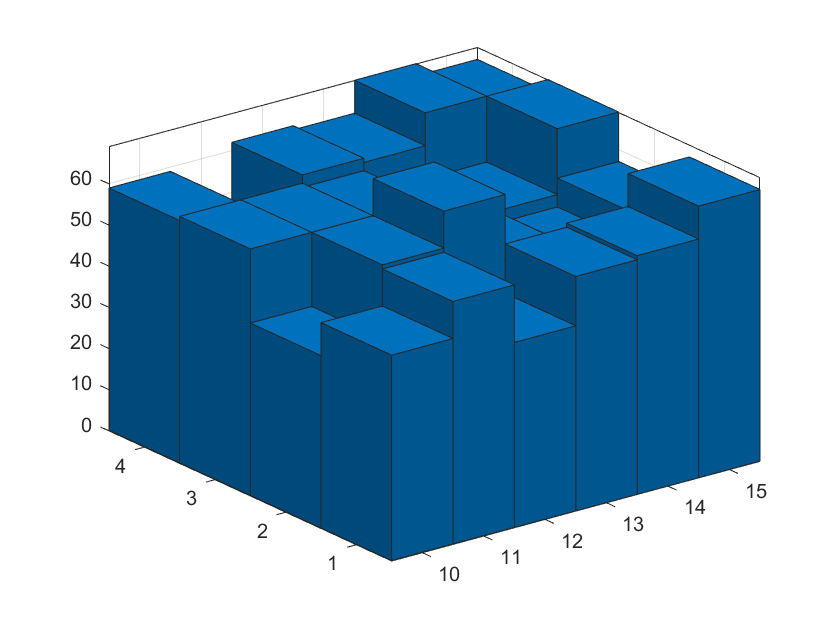

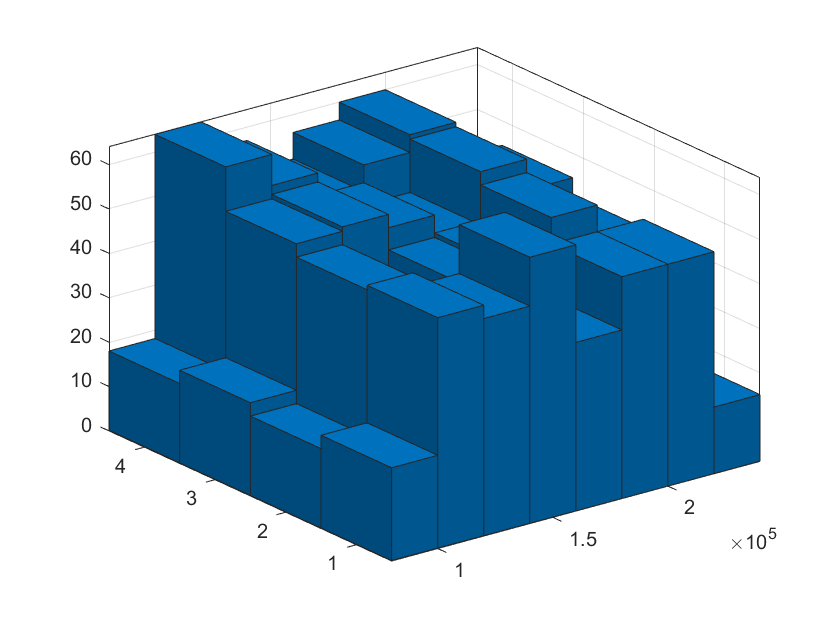

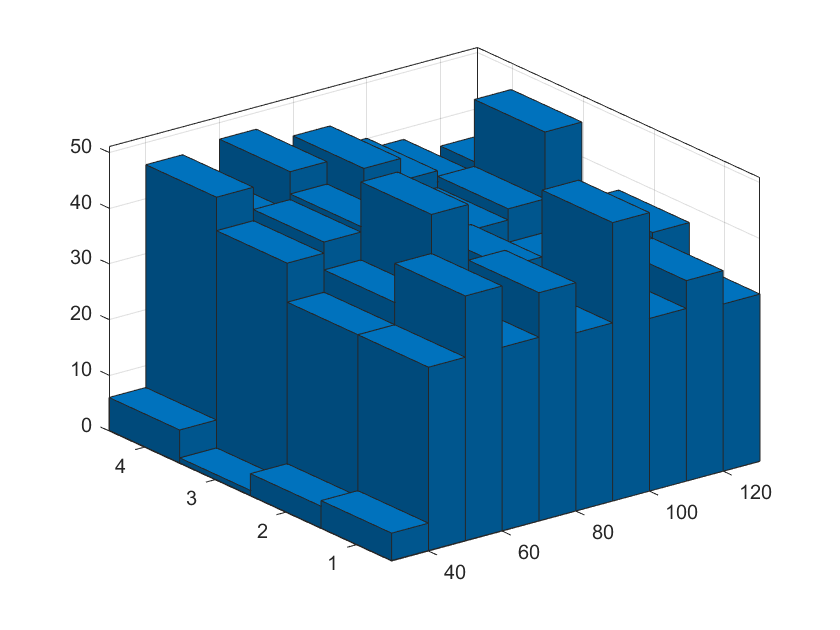

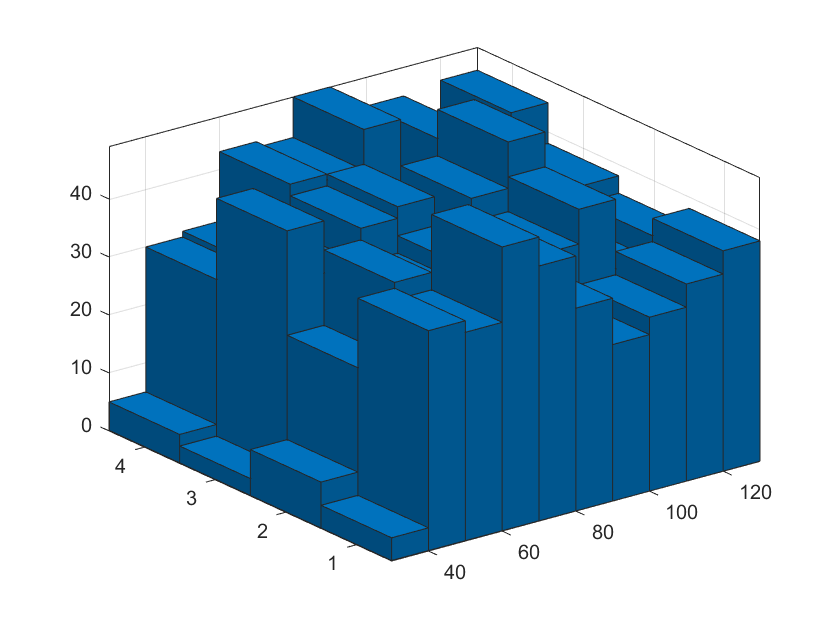

% Cross-verify with histograms and boxplots
for z=1:19
    figure
    histogram2(cdata(:,z),cdata(:,end))
end

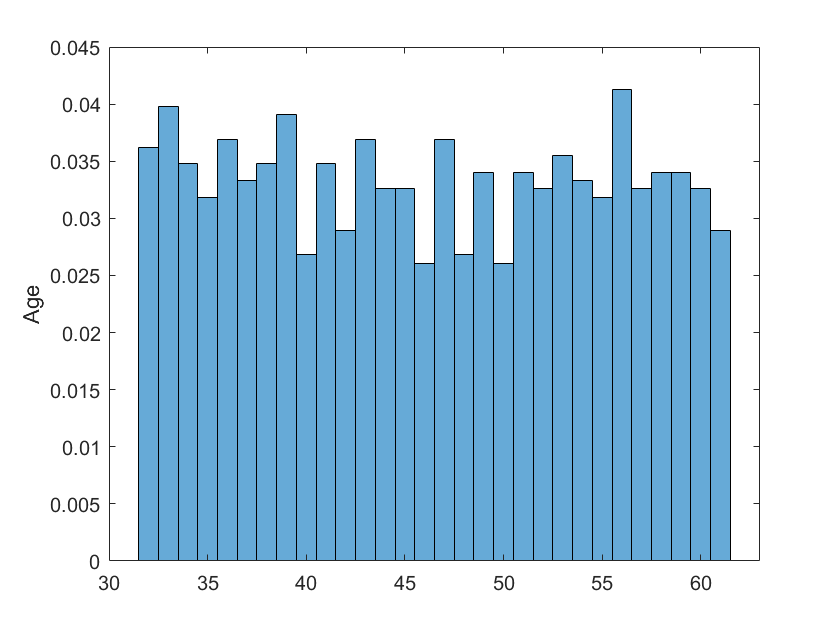

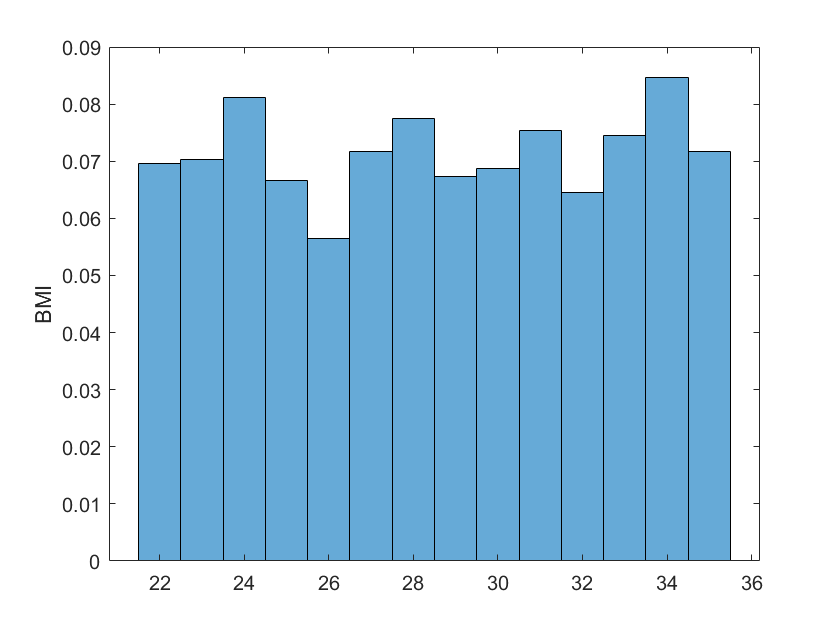

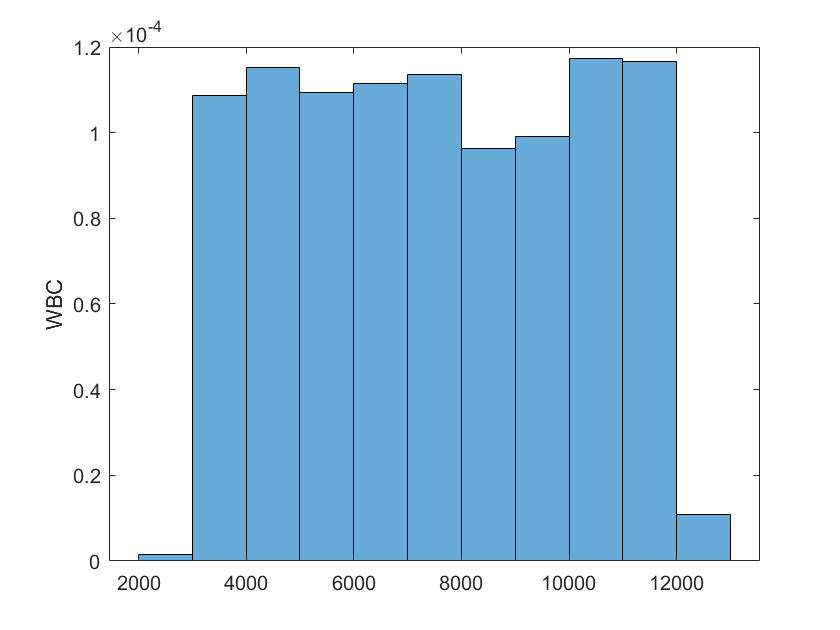

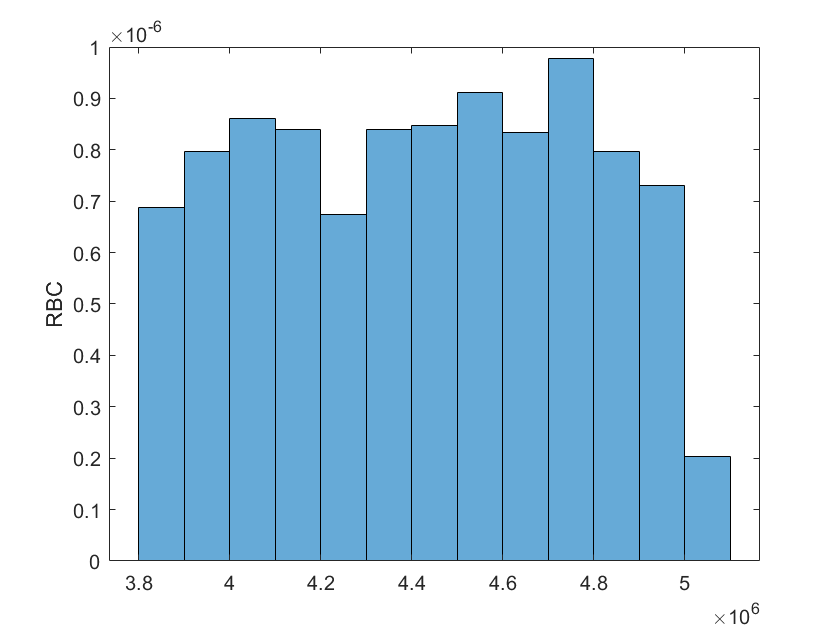

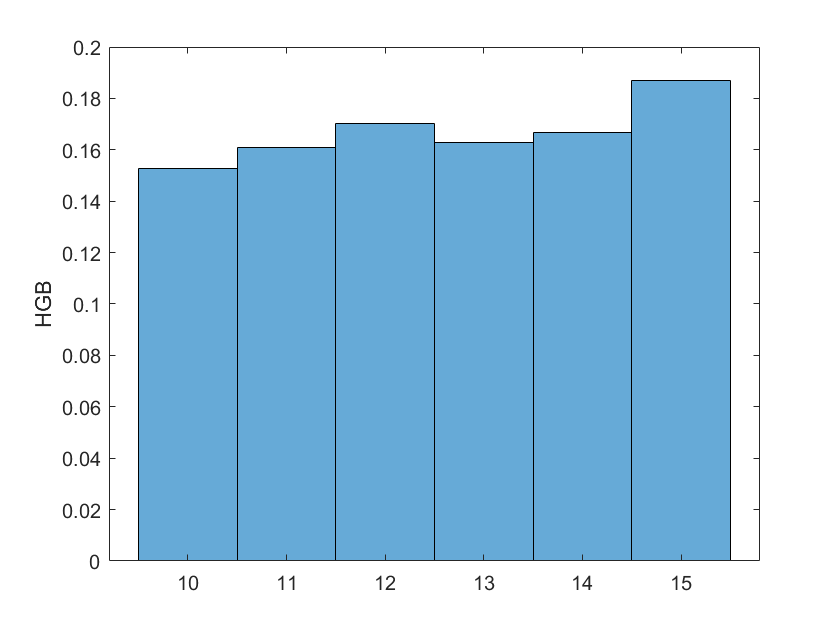

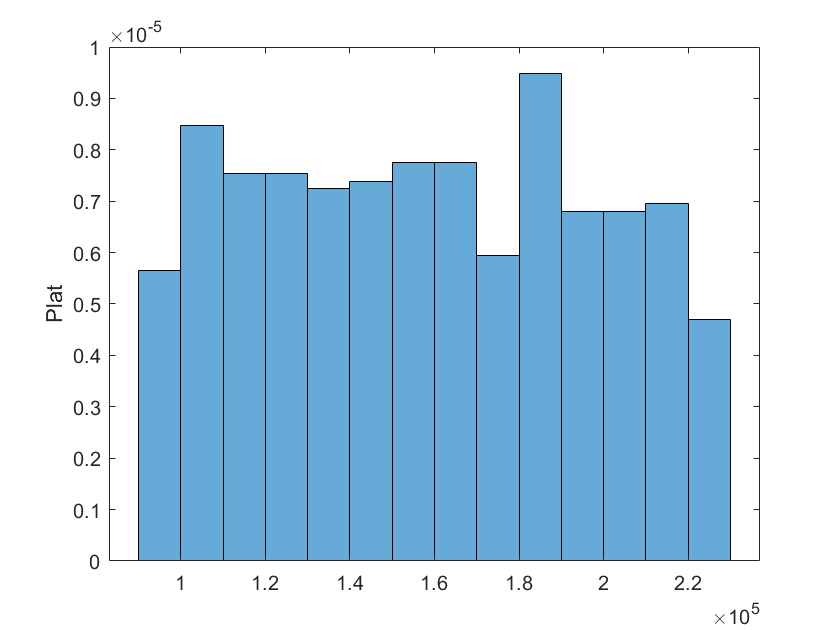

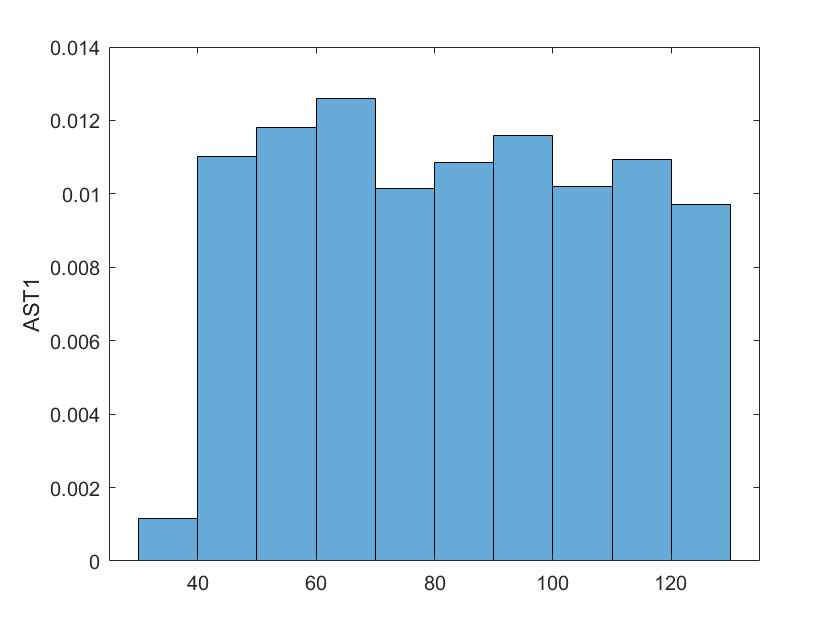

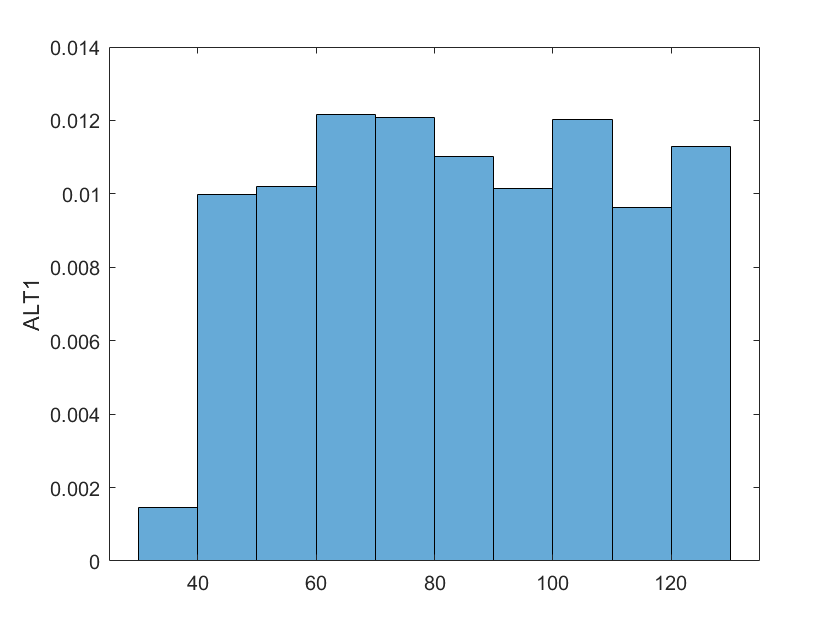

for z=1:19
    figure
    histogram(cdata(:,z),'Normalization',"pdf")
    ylabel(cdatat.Properties.VariableNames(z))
end

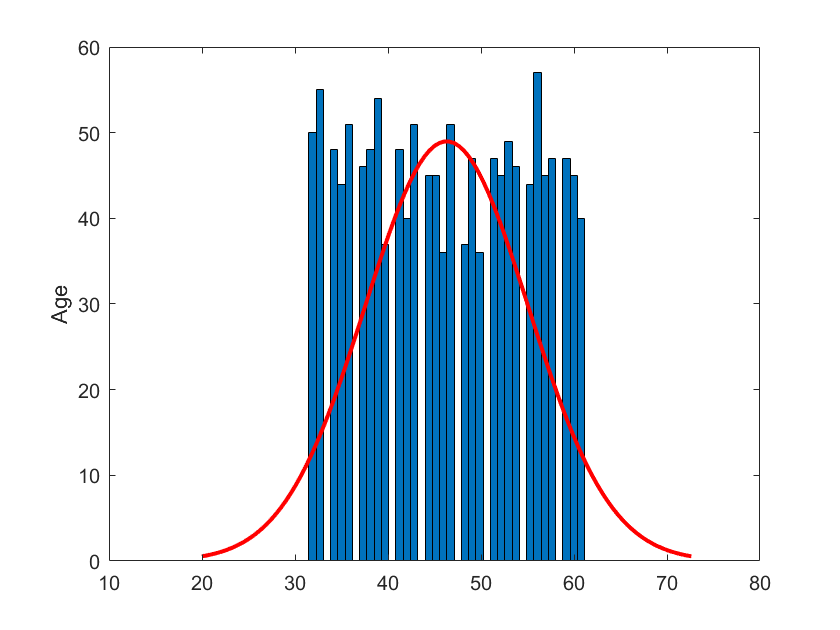

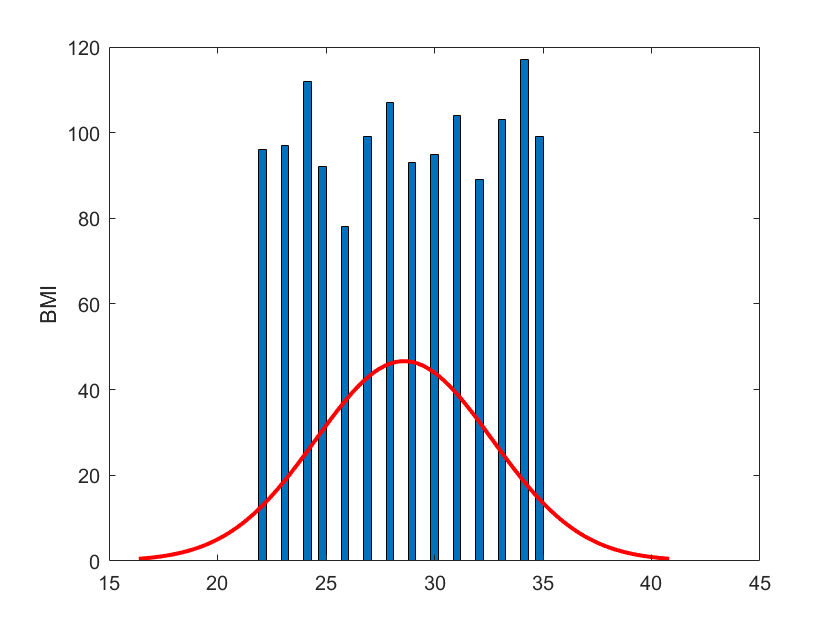

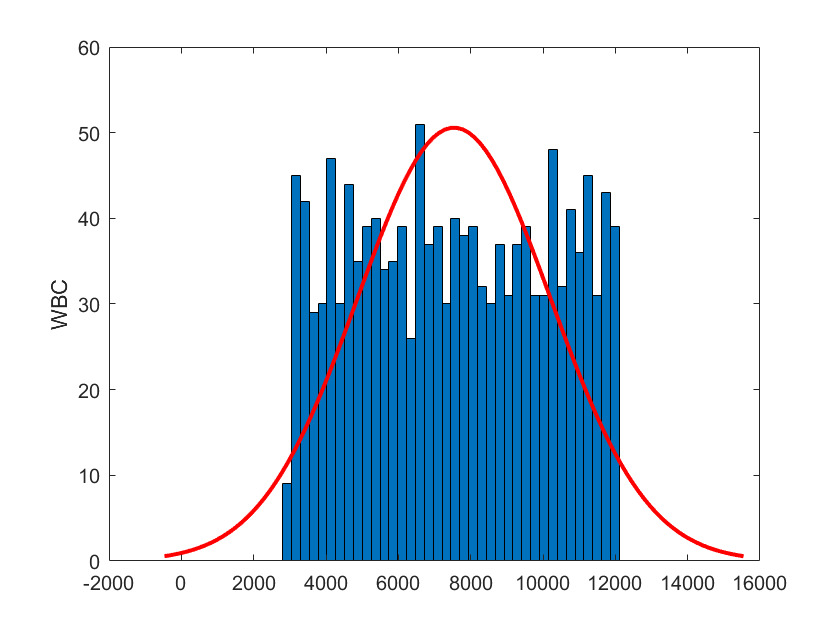

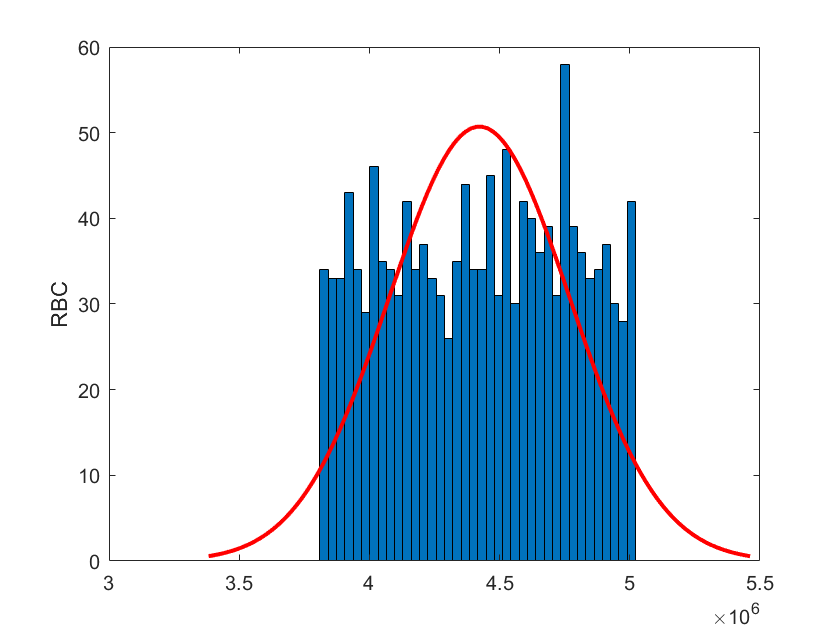

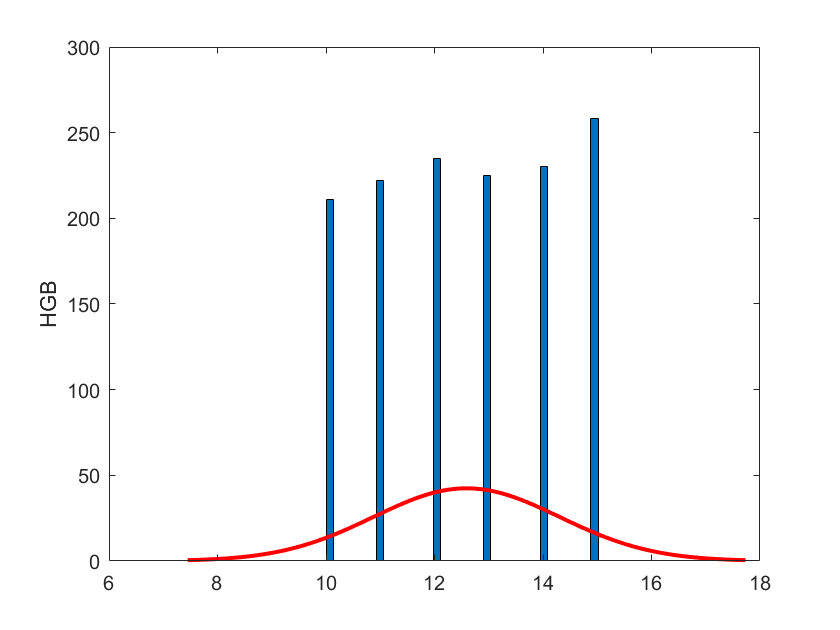

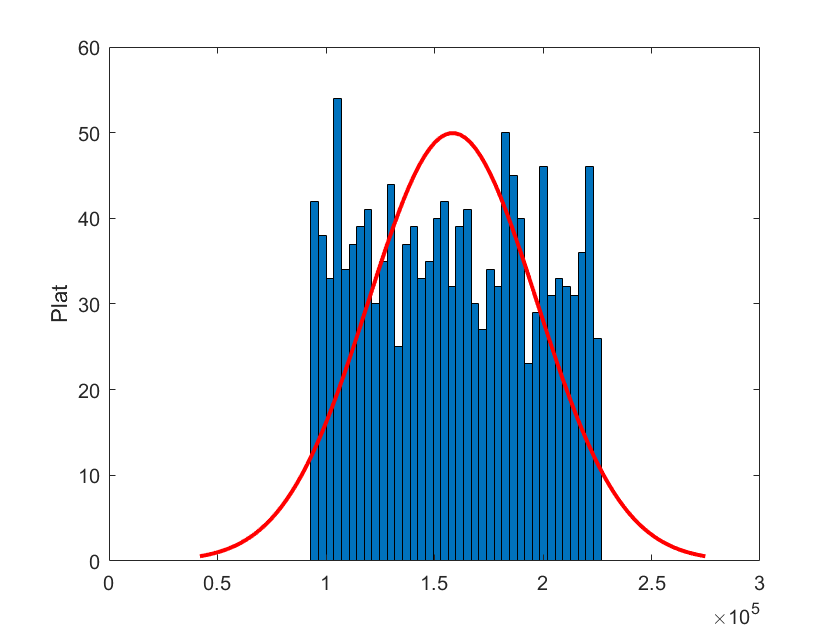

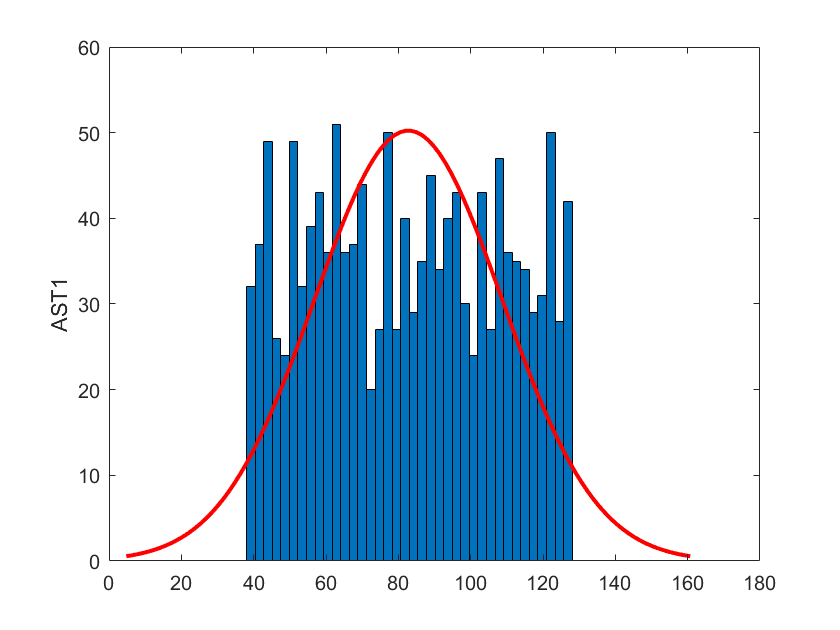

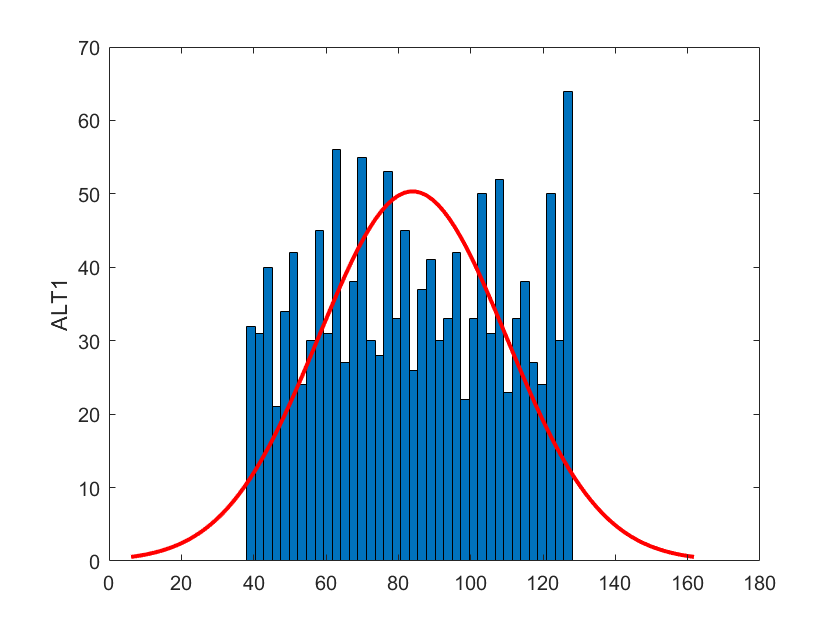

for z=1:19
    figure
    histfit(cdata(:,z))
    ylabel(cdatat.Properties.VariableNames(z))
end

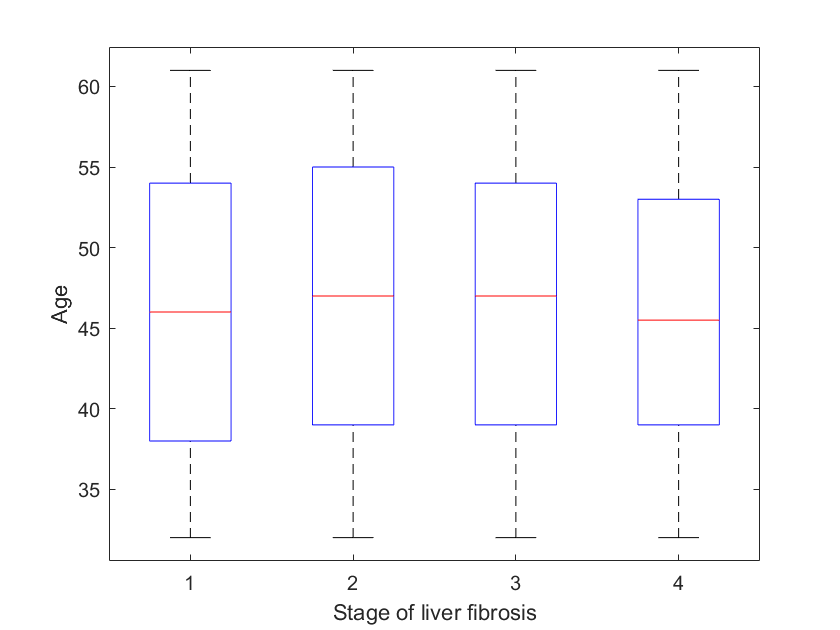

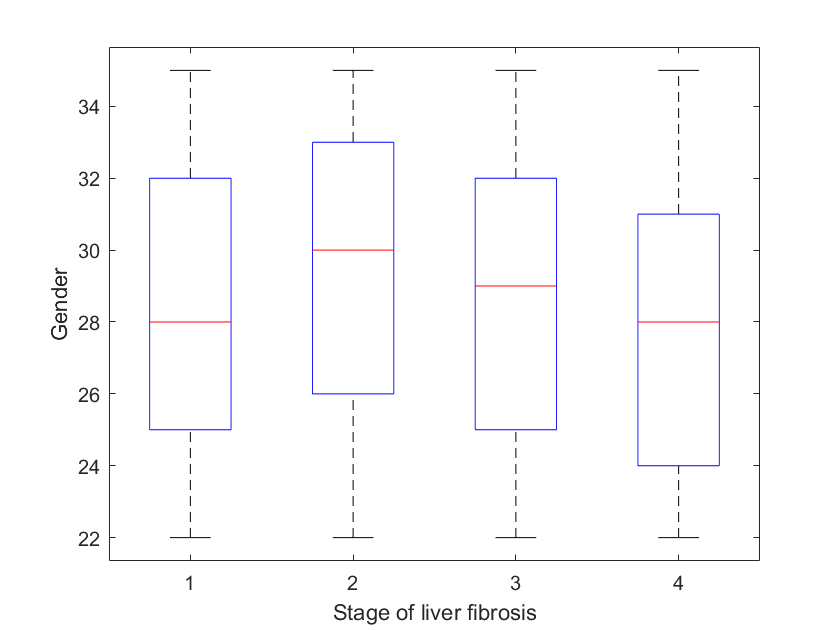

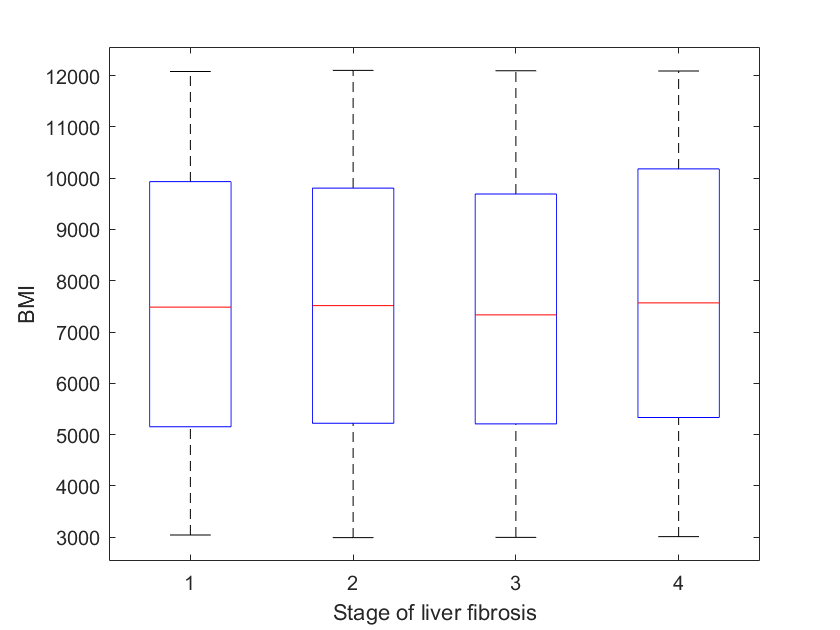

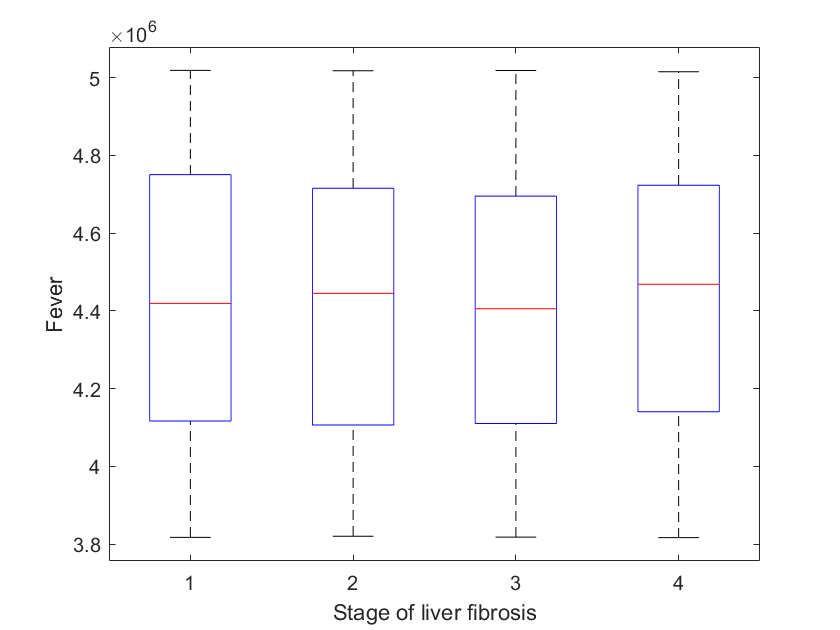

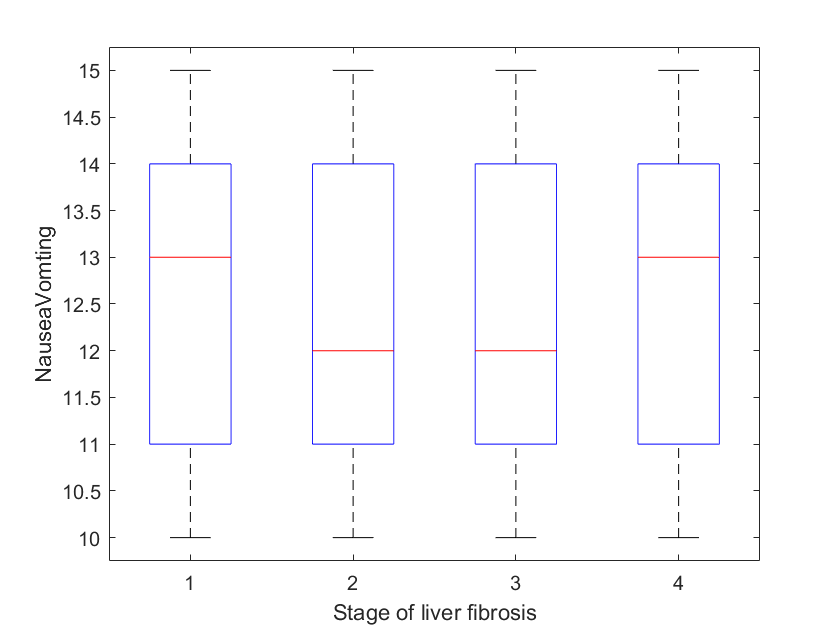

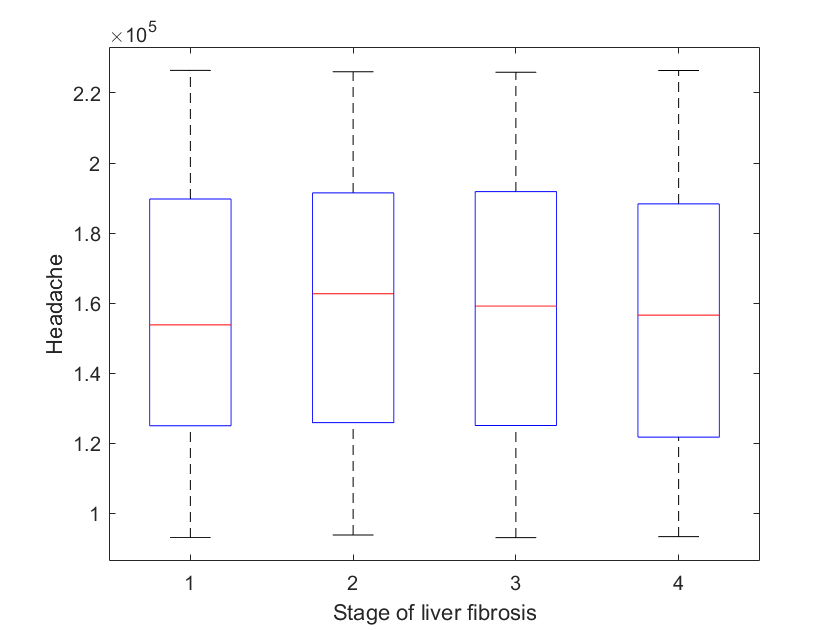

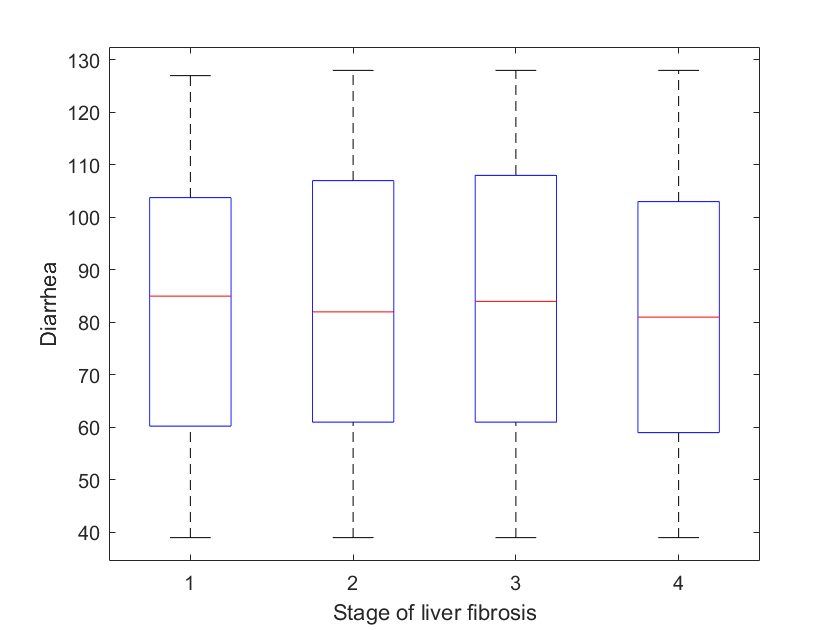

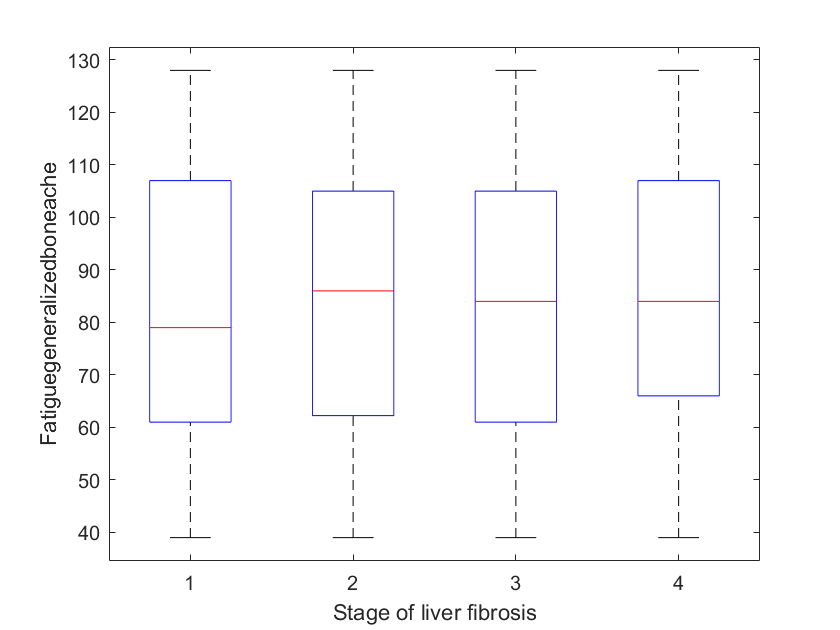

for z=1:19
    figure
    boxplot(cdata(:,z),cdata(:,end))
    xlabel('Stage of liver fibrosis')
    ylabel(HCV.Properties.VariableNames(z))
end

# Basic Statistical Values

% Stage and Continuous variables
sv=zeros(21,7);
for i=1:21
    sv(i,1)=min(cdatat.(i));
    sv(i,2)=max(cdatat.(i));
    sv(i,3)=range(cdatat.(i));
    sv(i,4)=mean(cdatat.(i));
    sv(i,5)=median(cdatat.(i));
    sv(i,6)=std(cdatat.(i));
    sv(i,7)=corr(cdatat.(i),cdatat.(21));
end
array2table(sv,'RowNames',cdatat.Properties.VariableNames,"VariableNames",{'Minimum','Maximum','Range','Mean','Median','Std.Dev.','Correlation'})

ans = 21×7 table
                    Minimum       Maximum        Range          Mean         Median       Std.Dev.     Correlation
                   __________    __________    __________    __________    __________    __________    ___________

    Age                    32            61            29        46.305            46        8.7717     -0.017586 
    BMI                    22            35            13        28.594            29        4.0731     -0.058403 
    WBC                  2991         12101          9110        7538.8          7514        2668.5      0.017791 
    RBC            3.8164e+06    5.0185e+06     1.202e+06    4.4223e+06    4.4385e+06    3.4657e+05  

% Stages and Categorical variables 
cadat=HCV_array(:,[2,4:10,29]);
cs=zeros(16,5);
for j=1:8
    cs(2*j-1,1)=sum(cadat(:,j)==1 & cadat(:,9)==1); % Stage 1
    cs(2*j-1,2)=sum(cadat(:,j)==1 & cadat(:,9)==2); % Stage 2
    cs(2*j-1,3)=sum(cadat(:,j)==1 & cadat(:,9)==3); % Stage 3
    cs(2*j-1,4)=sum(cadat(:,j)==1 & cadat(:,9)==4); % Stage 4
    cs(2*j-1,5)=sum(cadat(:,j)==1); % Total  
    cs(2*j,1)=sum(cadat(:,j)==2 & cadat(:,9)==1); % Stage 1
    cs(2*j,2)=sum(cadat(:,j)==2 & cadat(:,9)==2); % Stage 2
    cs(2*j,3)=sum(cadat(:,j)==2 & cadat(:,9)==3); % Stage 3
    cs(2*j,4)=sum(cadat(:,j)==2 & cadat(:,9)==4); % Stage 4
    cs(2*j,5)=sum(cadat(:,j)==2); % Total  
end
array2table(cs,'RowNames',{'Male','Female','Fever Absent','Fever Present','NausaeVomiting Absent',...
    'NausaeVomiting Present','Headache Absent','Headache Present','Diarrhea Absent','Diarrhea Present',...
    'Fatigue Absent','Fatigue Present','Jaundice Absent', 'Jaundice Present','GastricPain Absent', ...
    'Gastric Pain Present'},'VariableNames',{'Stage 1','Stage 2','Stage 3','Stage 4','Total'})

ans = 16×5 table
                              Stage 1    Stage 2    Stage 3    Stage 4    Total
                              _______    _______    _______    _______    _____

    Male                        172        181        162        190       705 
    Female                      164        149        192        171       676 
    Fever Absent                157        159        166        186       668 
    Fever Present               179        171        188        175       713 
    NausaeVomiting Absent       180        171        165        170       686 
    NausaeVomiting Present      156        159        189        191       695 
    Headache Absent             167        168       

## Data normalization

HCV_arr=normalize(HCV_array,'range');
dat=array2table(HCV_arr,'VariableNames',HCV.Properties.VariableNames)

dat = 1381×29 table
      Age       Gender      BMI       Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain      WBC         RBC       HGB      Plat       AST1       ALT1       ALT4       ALT12      ALT24       ALT36      ALT48     ALTafter24w    RNABase       RNA4       RNA12       RNAEOT      RNAEF      BaselinehistologicalGrading    Baselinehistologicalstaging
    ________    ______    ________

# Correlation

array2table(corr(HCV_arr),'Rownames',dat.Properties.VariableNames,'VariableNames',dat.Properties.VariableNames)

ans = 29×29 table
                                      Age          Gender         BMI          Fever       NauseaVomting     Headache      Diarrhea     Fatiguegeneralizedboneache     Jaundice     Epigastricpain       WBC            RBC           HGB           Plat          AST1          ALT1         ALT4         ALT12          ALT24         ALT36         ALT48       ALTafter24w     RNABase         RNA4           RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging

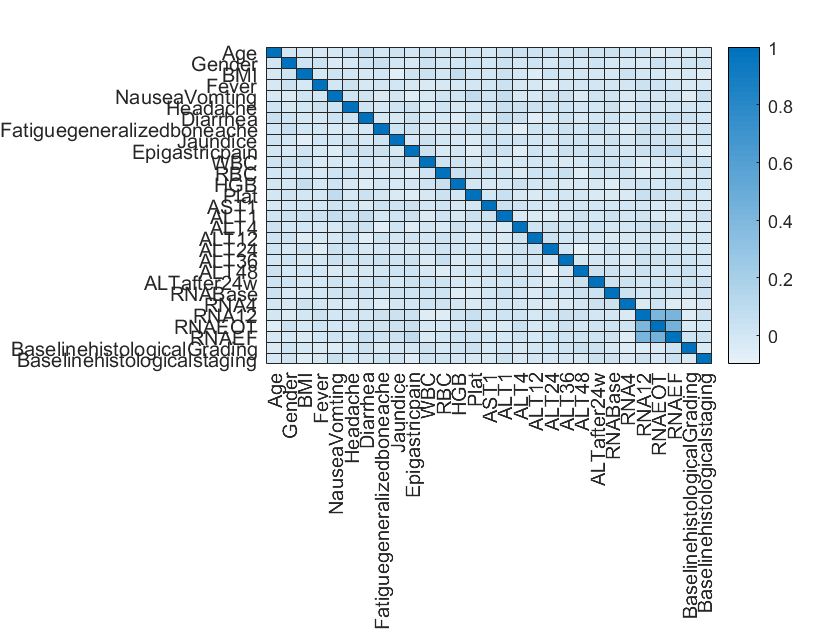

heatmap(corr(dat.Variables,'rows','complete'),'XDisplayLabels',string(dat.Properties.VariableNames),'YDisplayLabels',string(dat.Properties.VariableNames));

% Correlation matrix
% Takes longer to execute

%corrplot(dat)

for i=1:27
    [R1, pvalue1(i,1)]=corr(dat.(i),dat.(29));
    pvalue2(i,1)=anova1(dat.(i),dat.(29),'off');
    %[R3, pvalue3(i,1)]=corr(dat.(i),dat.(29),'type','Spearman'); for
    %ordinal/categorical data only
end

% Boneferroni and Benjamin Hochberg method
p_corrected1=27*pvalue1;
fdr1=mafdr(pvalue1);
p_corrected2=27*pvalue2;
fdr2=mafdr(pvalue2);
%p_corrected3=27*pvalue3;
%fdr3=mafdr(pvalue3);
%table(pvalue1,p_corrected1,fdr1,pvalue2,p_corrected2,fdr2,pvalue3,p_corrected3,fdr3,'Rownames',dat.Properties.VariableNames(1:27),'VariableNames',{'Pearson_Pval','Pearson_Qval','Pearson_FDR','Anova_Pval','Anova_Qval','Anova_FDR','Spearman_Pval','Spearman_Qval','Spearman_FDR'})

table(pvalue1,p_corrected1,fdr1,pvalue2,p_corrected2,fdr2,'Rownames',dat.Properties.VariableNames(1:27),'VariableNames',{'Pearson_Pval','Pearson_Qval','Pearson_FDR','Anova_Pval','Anova_Qval','Anova_FDR'})

ans = 27×6 table
                                  Pearson_Pval    Pearson_Qval    Pearson_FDR    Anova_Pval    Anova_Qval    Anova_FDR
                                  ____________    ____________    ___________    __________    __________    _________

    Age                              0.49214         13.288         0.61053        0.34477       9.3088             1 
    Gender                           0.70948         19.156          0.5721        0.10103       2.7279       0.66314 
    BMI                             0.035943        0.97047         0.57967      0.0093758      0.25315       0.24615 
    Fever                            0.26868         7.2544         0.48145         0.5496       14.839            

# Unsupervised

PCA can be used for mixed data type as long as categorical variables can be reduced to binary variables without loss of data. Variables should also be normalized before using.

% PCA without normalization
X=HCV_arr(:,1:end-2)

X =     0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896
    0.9310         0    0.7692         0         0    1.0000         0    1.0000    1.0000    1.0000    0.0735    0.6572    0.2000    0.7094    0.6742    0.7303    0.3146    0.1011    0.9101    0.7236    0.6911    0.6250    0.5498    0.6147    1.0000    0.4193    0.2997
    0.8966    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000         0    0.9653    0.0549    1.0000    0.2864    0.3034    0.7303    0.9213    0.6404   

stage=HCV_arr(:,29)

stage =     0.3333
    1.0000
         0
    1.0000
    0.6667
    0.3333
    0.3333
    0.3333
         0
         0


[coeff,score,latent,~,explained]=pca(X);
explained

explained =     7.8728
    7.6349
    7.3168
    7.2822
    7.1734
    6.9769
    6.7102
    6.4450
    4.4477
    3.3991


b=bar(explained)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
        YData: [7.8728 7.6349 7.3168 7.2822 7.1734 6.9769 6.7102 6.4450 4.4477 3.3991 2.9204 2.6990 2.6407 2.6087 2.5094 2.4840 2.4116 2.3982 2.3494 2.2584 2.1950 2.1192 1.6427 1.2741 1.2410 0.8659 0.1234]

  Show all properties


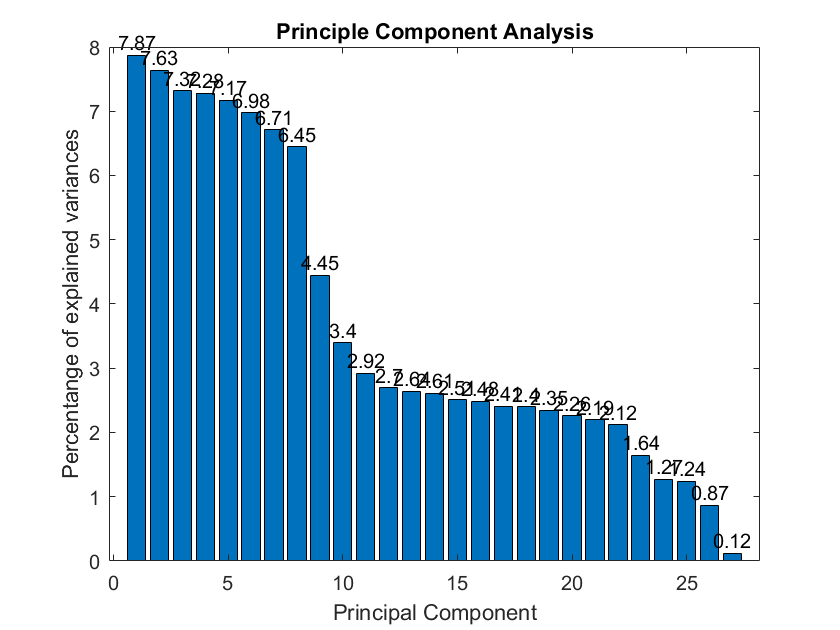

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,2));
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xlabel('Principal Component')
ylabel('Percentange of explained variances')
title('Principle Component Analysis')

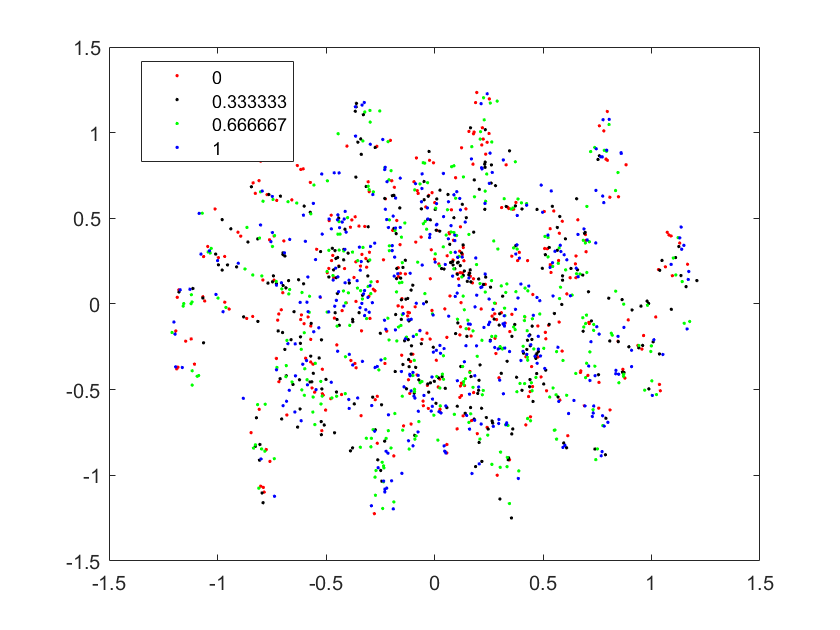

gscatter(score(:,1),score(:,2),stage,'rkgb')

Consider 0.05 as the variance threshold

features=HCV.Properties.VariableNames(1:end-2)';
PC1=abs(coeff(:,1));
sortrows(table(features,PC1),'PC1','descend')

ans = 27×2 table
               features                 PC1   
    ______________________________    ________

    {'NauseaVomting'             }      0.5587
    {'Fatiguegeneralizedboneache'}     0.55619
    {'Gender'                    }     0.42012
    {'Epigastricpain'            }     0.33121
    {'Headache'                  }     0.25554
    {'Diarrhea'                  }     0.12154
    {'ALT4'                      }    0.051366
    {'Plat'                      }    0.040148
    {'RNAEOT'                    }    0.038214
    {'Jaundice'                  }    0.035217
    {'ALT1'                      }    0.028753
    {'WBC'                       }    0.028405
    {'ALT24'                     }    0.027996
    {'RBC'                       }    0.027831
    {'ALT12'                     }    0.023729
    {'Fever'                     }    0.019822


PC2=abs(coeff(:,2));
sortrows(table(features,PC2),'PC2','descend')

ans = 27×2 table
               features                 PC2   
    ______________________________    ________

    {'Epigastricpain'            }     0.67329
    {'Diarrhea'                  }     0.43486
    {'Headache'                  }     0.37184
    {'Gender'                    }     0.29032
    {'Jaundice'                  }     0.25194
    {'Fever'                     }      0.2106
    {'NauseaVomting'             }     0.11214
    {'RNAEF'                     }    0.082696
    {'Fatiguegeneralizedboneache'}    0.043748
    {'RNAEOT'                    }    0.038597
    {'HGB'                       }    0.035639
    {'ALT1'                      }    0.029961
    {'Plat'                      }    0.028119
    {'Age'                       }    0.020355
    {'RNABase'                   }    0.016503
    {'RBC'                       }    0.016031


PC3=abs(coeff(:,3));
sortrows(table(features,PC3),'PC3','descend')

ans = 27×2 table
               features                 PC3   
    ______________________________    ________

    {'Fever'                     }     0.65921
    {'Gender'                    }     0.45424
    {'Headache'                  }     0.43757
    {'Diarrhea'                  }     0.37506
    {'Epigastricpain'            }    0.092522
    {'HGB'                       }    0.062919
    {'Fatiguegeneralizedboneache'}    0.058957
    {'ALT1'                      }    0.057055
    {'ALT24'                     }    0.038654
    {'NauseaVomting'             }    0.035657
    {'RNAEOT'                    }    0.028556
    {'WBC'                       }    0.027106
    {'BMI'                       }    0.024459
    {'AST1'                      }    0.023647
    {'RNA4'                      }    0.022816
    {'ALT12'                     }    0.021578


PC4=abs(coeff(:,4));
sortrows(table(features,PC4),'PC4','descend')

ans = 27×2 table
               features                 PC4   
    ______________________________    ________

    {'Diarrhea'                  }      0.5267
    {'Jaundice'                  }     0.48609
    {'Headache'                  }     0.46056
    {'Gender'                    }      0.3342
    {'Fever'                     }     0.25717
    {'Fatiguegeneralizedboneache'}     0.20823
    {'Epigastricpain'            }     0.20624
    {'Plat'                      }     0.05522
    {'AST1'                      }    0.036226
    {'BMI'                       }    0.035082
    {'ALT12'                     }    0.034255
    {'NauseaVomting'             }    0.030338
    {'RNA4'                      }    0.024099
    {'RNAEF'                     }    0.019128
    {'RNAEOT'                    }    0.018718
    {'WBC'                       }    0.017758


%K-means Clustering for continuous variables
k_values=2:5;
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idx=kmeans(HCV_arr(:,[1,3,11:end-2]),k_values(i));
    s=silhouette(HCV_arr(:,[1,3,11:end-2]),idx);
    s_score(i)=mean(s);
end
table(k_values',s_score)

ans = 4×2 table
    Var1    s_score 
    ____    ________

     2       0.14243
     3       0.11728
     4      0.099189
     5      0.094928


k=find(s_score==max(s_score))+1

k = 2

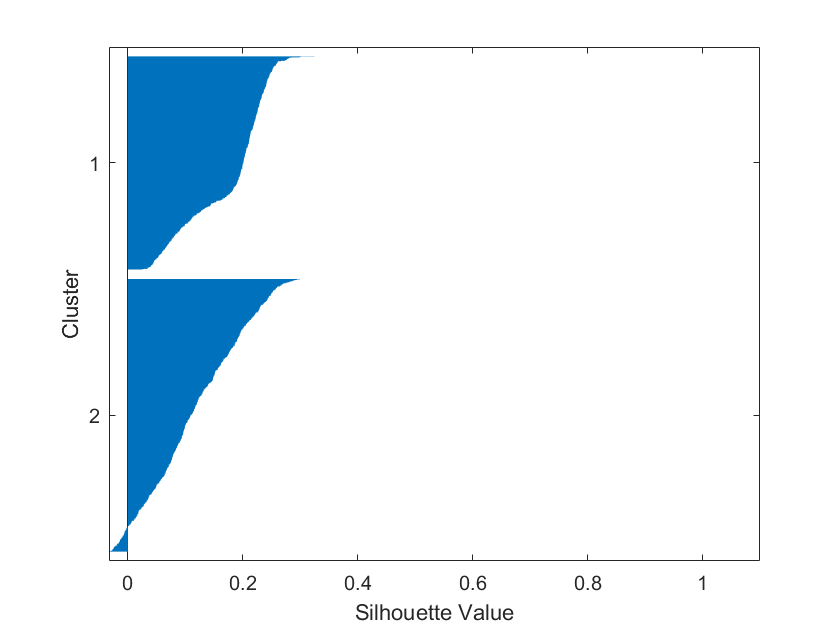


idx=kmeans(HCV_arr(:,[1,3,11:end-2]),k);
silhouette(HCV_arr(:,[1,3,11:end-2]),idx)

Can be used to classify into advanced and moderate fibrosis

%K-mediods clustering for categorical variables
k_values=2:5;
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idx=kmedoids(HCV_arr(:,[2,4:10]),k_values(i));
    s=silhouette(HCV_arr(:,[2,4:10]),idx);
    s_score(i)=mean(s);
end
table(k_values',s_score)

ans = 4×2 table
    Var1    s_score
    ____    _______

     2      0.16331
     3      0.15183
     4       0.1511
     5      0.15443


k=find(s_score==max(s_score))+1

k = 2

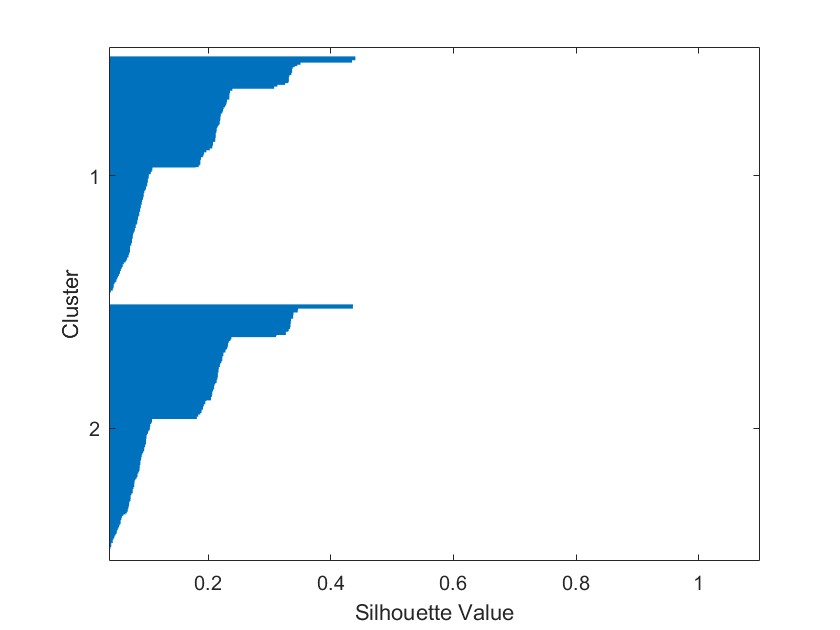


idx=kmedoids(HCV_arr(:,[2,4:10]),k);
silhouette(HCV_arr(:,[2,4:10]),idx)

# Supervised

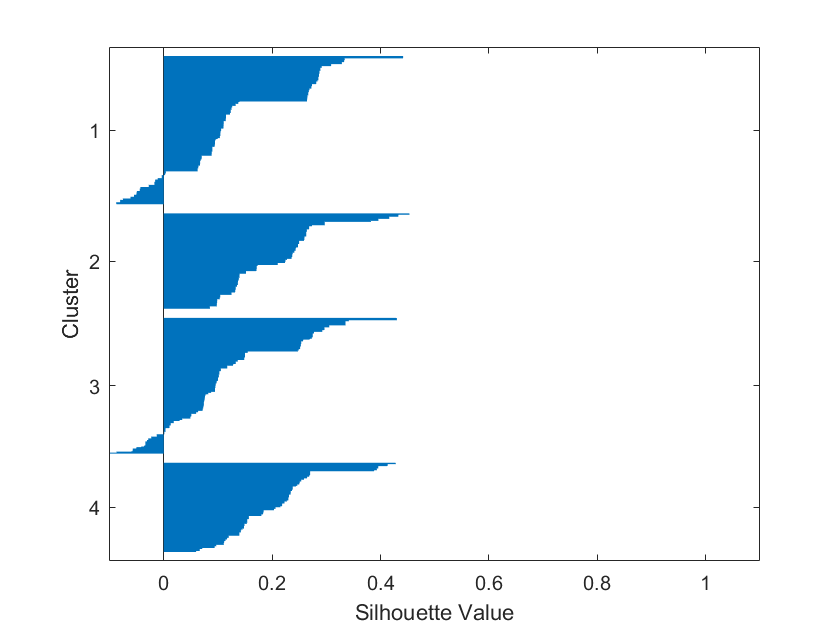

idx=kmedoids(HCV_arr(:,[2,4:10]),4,"Distance","hamming");
silhouette(HCV_arr(:,[2,4:10]),idx)

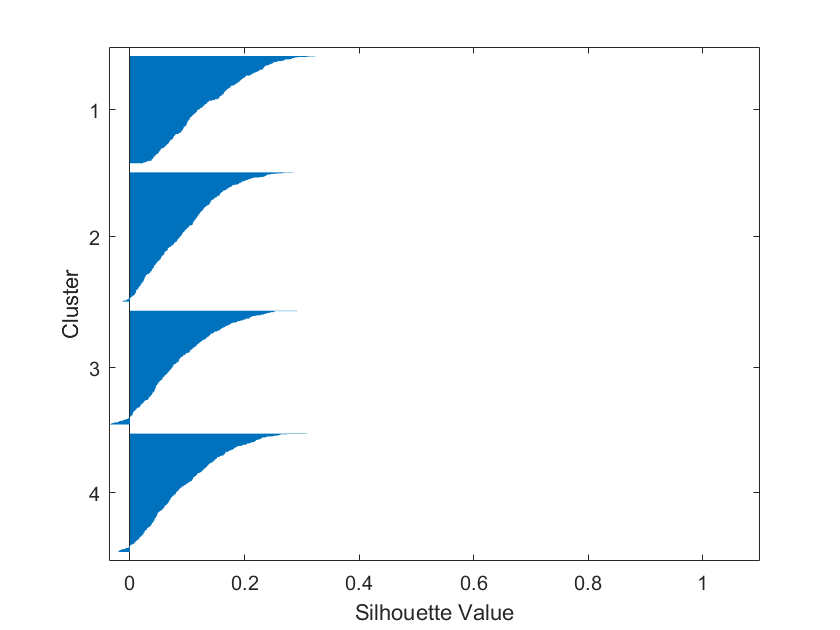

idx=kmeans(HCV_arr(:,[1,3,11:end-2]),4);
silhouette(HCV_arr(:,[1,3,11:end-2]),idx)

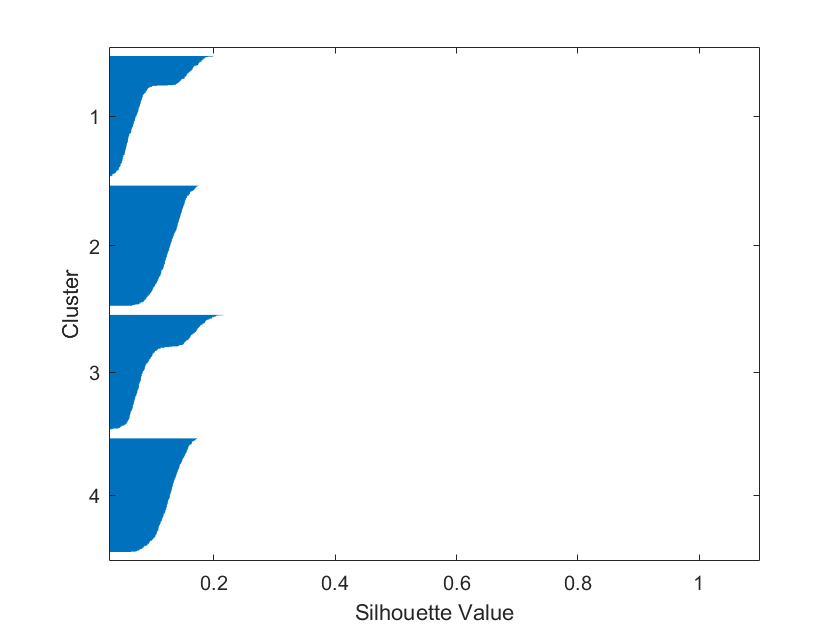

idx=kmeans(HCV_arr,4,'Distance',"sqeuclidean");
silhouette(HCV_arr,idx)

# Aim: Predict stages of fibrosis

## Train and Test Data

x=HCV_arr(:,1:27);
y=HCV_arr(:,29);
[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(x,y,0.7);

### Multinomial Logistic Regression

[b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain))

b1 =    -0.7634   -0.2200   -0.3290
    0.2761    0.7221    0.3182
   -0.0322   -0.1349    0.2020
    0.4981    0.9650    0.3917
    0.2279    0.0328    0.2401
   -0.1964   -0.1871   -0.0939
   -0.1690   -0.0727   -0.1011
    0.1316   -0.1548   -0.0521
   -0.1314   -0.0095   -0.0169
   -0.1005    0.0735   -0.1380


dev1 = 2.6102e+03

stats1 = struct with fields:
         beta: [28×3 double]
          dfe: 2817
         sfit: 1.0159
            s: 1
      estdisp: 0
         covb: [84×84 double]
    coeffcorr: [84×84 double]
           se: [28×3 double]
            t: [28×3 double]
            p: [28×3 double]
        resid: [967×4 double]
       residp: [967×4 double]
       residd: [967×1 double]


[val,pred1]=max(mnrval(b1,Xtest)')

val =     0.3443    0.3691    0.3919    0.3101    0.3199    0.3925    0.3690    0.4254    0.3604    0.3066    0.3508    0.3284    0.2791    0.3099    0.2983    0.3597    0.3198    0.3541    0.2889    0.3211    0.3067    0.2945    0.3162    0.3148    0.2893    0.3297    0.3101    0.3254    0.3531    0.3063    0.4025    0.2762    0.2897    0.3380    0.3802    0.3356    0.3633    0.3714    0.2749    0.3126    0.3040    0.2685    0.2913    0.3225    0.4082    0.4143    0.2733    0.2852    0.3270    0.3436


pred1 =      4     4     1     3     4     2     4     4     3     2     3     4     2     3     2     1     1     2     3     3     4     1     4     4     4     4     1     4     2     3     2     2     1     2     4     4     2     3     3     3     2     2     4     3     2     2     4     4     1     3


pred1=normalize(pred1','range')

pred1 =     1.0000
    1.0000
         0
    0.6667
    1.0000
    0.3333
    1.0000
    1.0000
    0.6667
    0.3333


accuracy1=sum(pred1==Ytest)/length(Ytest)

accuracy1 = 0.2754

confusionmat(double(Ytest),double(pred1))

Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 414
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          18                26                21                38      
    Actual_class2          19                24                26                28      
    Actual_class3          17                18                35                34      
    Actual_class4          21                26                26                37      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =     18    26    21    38
    19    24    26    28
    17    18    35    34
    21    26    26    37


## 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy1=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x(train,:);
    Xtest=x(test,:);
    Ytrain=y(train,:);
    Ytest=y(test,:);
    
    %Multinomial Logistic Regression
    [b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain));
    [~,pred1]=max(mnrval(b1,Xtest)');
    pred1=normalize(pred1','range');
    accuracy1(i)=sum(pred1==Ytest)/length(Ytest)
    confusionmat(double(Ytest),double(pred1))
end

accuracy1 =     0.2113         0         0         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 194
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           8                 9                15                21      
    Actual_class2          10                 6                10                14      
    Actual_class3          12                12                10                15      
    Actual_class4          12                12                11                17      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      8     9    15    21
    10     6    10    14
    12    12    10    15
    12    12    11    17


accuracy1 =     0.2113    0.2332         0         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           9                 5                11                14      
    Actual_class2          16                 6                 8                20      
    Actual_class3          11                12                13                26      
    Actual_class4          11                 6                 8                17      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      9     5    11    14
    16     6     8    20
    11    12    13    26
    11     6     8    17


accuracy1 =     0.2113    0.2332    0.2176         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           9                18                12                19      
    Actual_class2           5                 5                15                16      
    Actual_class3          11                 9                12                12      
    Actual_class4           8                10                16                16      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      9    18    12    19
     5     5    15    16
    11     9    12    12
     8    10    16    16


accuracy1 =     0.2113    0.2332    0.2176    0.2371         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 194
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           7                4                 16                24      
    Actual_class2          14                5                 13                17      
    Actual_class3           9                5                 12                20      
    Actual_class4          11                1                 14                22      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      7     4    16    24
    14     5    13    17
     9     5    12    20
    11     1    14    22


accuracy1 =     0.2113    0.2332    0.2176    0.2371    0.2435


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           9                10                10                15      
    Actual_class2          13                 7                12                10      
    Actual_class3          14                 8                11                13      
    Actual_class4          15                 8                18                20      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      9    10    10    15
    13     7    12    10
    14     8    11    13
    15     8    18    20


avg_accuracy_5=mean(accuracy1)

avg_accuracy_5 = 0.2286

# Aim: Predict Advanced fibrosis

## Train and Test Data

x=HCV_arr(:,1:27);
y=zeros(1381,1);
for i=1:1381
    if HCV_array(i,29)>2
        y(i)=1;
    end
end
[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(x,y,0.7);

### Multinomial Logistic Regression

[b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain))

b1 =    -0.0917
    0.0708
   -0.2400
    0.3785
   -0.0688
   -0.2173
    0.0074
   -0.0781
    0.0180
   -0.1269


dev1 = 1.3121e+03

stats1 = struct with fields:
         beta: [28×1 double]
          dfe: 939
         sfit: 1.0147
            s: 1
      estdisp: 0
         covb: [28×28 double]
    coeffcorr: [28×28 double]
           se: [28×1 double]
            t: [28×1 double]
            p: [28×1 double]
        resid: [967×2 double]
       residp: [967×2 double]
       residd: [967×1 double]


[val,pred1]=max(mnrval(b1,Xtest)')

val =     0.6741    0.6059    0.5154    0.6316    0.6255    0.6774    0.6076    0.5877    0.5111    0.5517    0.5561    0.5855    0.5847    0.5839    0.6056    0.6993    0.5696    0.5557    0.5077    0.6370    0.6056    0.5437    0.6415    0.5362    0.5986    0.5228    0.6198    0.5088    0.5410    0.5418    0.5655    0.5739    0.5097    0.5430    0.5900    0.6040    0.6276    0.5281    0.5335    0.5825    0.6319    0.5438    0.5535    0.5316    0.5068    0.5810    0.5322    0.5314    0.6605    0.5817


pred1 =      2     2     2     1     1     2     2     2     2     2     2     2     2     2     2     1     2     1     2     2     2     1     2     1     2     1     1     1     1     2     1     2     2     1     2     2     2     2     2     2     2     2     1     1     2     2     2     2     2     2


pred1=normalize(pred1','range')

pred1 =      1
     1
     1
     0
     0
     1
     1
     1
     1
     1


accuracy1=sum(pred1==Ytest)/length(Ytest)

accuracy1 = 0.5193

confusionmat(double(Ytest),double(pred1))

Class List in given sample
     0
     1


Total Instance = 414
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          82               132      
    Actual_class2          67               133      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          82]    [          132]
    'TrueNegative=TN'    [          67]    [          133]

Over all valuses
                          Accuracy: 0.5193
                             Error: 0.4807
                       Sensitivity: 0.3832
                       Specificity: 0.6650
                         Precision: 0.5503
                 FalsePositiveRate: 0.3350
                          F1_score: 0.4518
    MatthewsCorrelationCoefficient: 0.0502
           

ans =     82   132
    67   133


stats1.p

ans =     0.8829
    0.7425
    0.0697
    0.0773
    0.6012
    0.1029
    0.9559
    0.5546
    0.8915
    0.3370


## 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy1=zeros(1,fold);
accuracy2=zeros(1,fold);
precision2=zeros(1,fold);
recall2=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x(train,:);
    Xtest=x(test,:);
    Ytrain=y(train,:);
    Ytest=y(test,:);
    
    %Multinomial Logistic Regression
    [b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain));
    [~,pred1]=max(mnrval(b1,Xtest)');
    pred1=normalize(pred1','range');
    accuracy1(i)=sum(pred1==Ytest)/length(Ytest);
    confusionmat(double(Ytest),double(pred1))
    
    %Linear Regression
    b2=fitlm(Xtrain,Ytrain);
    pred2=round(predict(b2,Xtest));
    accuracy2(i)=sum(pred2==Ytest)/length(Ytest);
    precision2(i)=sum(pred2==1 & Ytest==1)/sum(pred2==1);
    recall2(i)=sum(pred2==1 & Ytest==1)/sum(Ytest==1);
    
end

Class List in given sample
     0
     1


Total Instance = 193
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          41                53      
    Actual_class2          43                56      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          41]    [           53]
    'TrueNegative=TN'    [          43]    [           56]

Over all valuses
                          Accuracy: 0.5026
                             Error: 0.4974
                       Sensitivity: 0.4362
                       Specificity: 0.5657
                         Precision: 0.4881
                 FalsePositiveRate: 0.4343
                          F1_score: 0.4607
    MatthewsCorrelationCoefficient: 0.0018
           

ans =     41    53
    43    56


Class List in given sample
     0
     1


Total Instance = 194
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          39                60      
    Actual_class2          34                61      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          39]    [           60]
    'TrueNegative=TN'    [          34]    [           61]

Over all valuses
                          Accuracy: 0.5155
                             Error: 0.4845
                       Sensitivity: 0.3939
                       Specificity: 0.6421
                         Precision: 0.5342
                 FalsePositiveRate: 0.3579
                          F1_score: 0.4535
    MatthewsCorrelationCoefficient: 0.0372
           

ans =     39    60
    34    61


Class List in given sample
     0
     1


Total Instance = 193
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          34                65      
    Actual_class2          32                62      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          34]    [           65]
    'TrueNegative=TN'    [          32]    [           62]

Over all valuses
                          Accuracy: 0.4974
                             Error: 0.5026
                       Sensitivity: 0.3434
                       Specificity: 0.6596
                         Precision: 0.5152
                 FalsePositiveRate: 0.3404
                          F1_score: 0.4121
    MatthewsCorrelationCoefficient: 0.0032
           

ans =     34    65
    32    62


Class List in given sample
     0
     1


Total Instance = 194
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          41                44      
    Actual_class2          59                50      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          41]    [           44]
    'TrueNegative=TN'    [          59]    [           50]

Over all valuses
                          Accuracy: 0.4691
                             Error: 0.5309
                       Sensitivity: 0.4824
                       Specificity: 0.4587
                         Precision: 0.4100
                 FalsePositiveRate: 0.5413
                          F1_score: 0.4432
    MatthewsCorrelationCoefficient: 0.0585
           

ans =     41    44
    59    50


Class List in given sample
     0
     1


Total Instance = 193
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          43                47      
    Actual_class2          47                56      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          43]    [           47]
    'TrueNegative=TN'    [          47]    [           56]

Over all valuses
                          Accuracy: 0.5130
                             Error: 0.4870
                       Sensitivity: 0.4778
                       Specificity: 0.5437
                         Precision: 0.4778
                 FalsePositiveRate: 0.4563
                          F1_score: 0.4778
    MatthewsCorrelationCoefficient: 0.0215
           

ans =     43    47
    47    56


avg_accuracy_multinom=mean(accuracy1)

avg_accuracy_multinom = 0.4995

avg_accuracy_lm=mean(accuracy2)

avg_accuracy_lm = 0.5005

avg_precision_lm=mean(precision2)

avg_precision_lm = 0.5172

avg_recall_lm=mean(recall2)

avg_recall_lm = 0.5761

## Random Forest

RFmodel=TreeBagger(100,Xtrain,Ytrain,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [774x27]
                    Training Y:              [774x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '0'             '1'

  Properties, Methods


Ypred=predict(RFmodel,Xtest) % RF gives output in cell array format

Ypred = 193×1 cell array
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'0'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'0'}
    {'0'}
    {'1'}
    {'0'}
    {'0'}
    {'0'}
    {'1'}
    {'0'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}
    {'1'}


Ypred=categorical(Ypred) % cell array to categorical array

Ypred = 193×1 categorical array
     1 
     1 
     1 
     0 
     1 
     1 
     1 
     1 
     0 
     1 
     1 
     0 
     1 
     0 
     1 
     1 
     1 
     0 
     0 
     1 
     0 
     0 
     0 
     1 
     0 
     1 
     1 
     1 
     1 
     1 


accuracy4=sum(Ypred==categorical(Ytest))/length(Ytest)

accuracy4 = 0.5181

confusionmat(double(Ypred),double(categorical(Ytest)))

Class List in given sample
     1
     2


Total Instance = 193
class1==>1
class2==>2
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          35                38      
    Actual_class2          55                65      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          35]    [           38]
    'TrueNegative=TN'    [          55]    [           65]

Over all valuses
                          Accuracy: 0.5181
                             Error: 0.4819
                       Sensitivity: 0.4795
                       Specificity: 0.5417
                         Precision: 0.3889
                 FalsePositiveRate: 0.4583
                          F1_score: 0.4294
    MatthewsCorrelationCoefficient: 0.0205
           

ans =     35    38
    55    65


ans = 'double'

Error using lasso (line 294)
The value of Y must be a numeric array.

Initial columns included: none
Final columns included:  none
    'Coeff'          'Std.Err.'    'Status'    'P'     
    [-6.8404e-04]    [  0.0590]    'Out'       [0.9907]
    [     0.0293]    [  0.0360]    'Out'       [0.4165]
    [    -0.0744]    [  0.0569]    'Out'       [0.1912]
    [     0.0211]    [  0.0360]    'Out'       [0.5569]
    [     0.0597]    [  0.0359]    'Out'       [0.0969]
    [    -0.0027]    [  0.0360]    'Out'       [0.9398]
    [    -0.0469]    [  0.0359]    'Out'       [0.1928]
    [    -0.0438]    [  0.0359]    'Out'       [0.2234]
    [     0.0167]    [  0.0360]    'Out'       [0.6435]
    [    -0.0441]    [  0.0359]    'Out'       [0.2206]
    [     0.0383]    [  0.0608]    'Out'       [0.5288]
    [    -0.0896]    [  0.0626]    'Out'       [0.1531]
    [     0.0306]    [  0.0533]    'Out'       [0.5657]
    [    -0.0428]    [  0.0623]    'Out'       [0.4921]
    [    -0.0436]    [  0.0621]    'Out'       [0.4831]
    [    -0.0488]    [  0.0619]    'Out'   

b3 =    -0.0007
    0.0293
   -0.0744
    0.0211
    0.0597
   -0.0027
   -0.0469
   -0.0438
    0.0167
   -0.0441


inmodel = 1×27 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


b3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


pred3 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


accuracy3 = 0.4663

### Selecting subset of features

mdl1=fitlm(HCV_arr(:,[1:27]),HCV_array(:,29)>2,'CategoricalVars',{'x2','x4','x5','x6','x7','x8','x9','x10'})

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27

Estimated Coefficients:
                    Estimate        SE        tStat        pValue  
                   __________    ________    ________    __________

    (Intercept)        0.5414     0.12464      4.3437    1.5058e-05
    x1              -0.042526    0.044582    -0.95389       0.34031
    x2_1             0.041713    0.027045      1.5424       0.12322
    x3               -0.10922    0.043299     -2.5225      0.011767
    x4_1             -0.02126    0.026998    -0.78744       0.43116
    x5_1             0.056584    0.027178       2.082       0.037

newmdl1=step(mdl1)

1. Adding x6:x13, FStat = 6.9063, pValue = 0.0086867


newmdl1 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x7 + x8 + x9 + x10 + x11 + x12 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x6*x13

Estimated Coefficients:
                    Estimate        SE        tStat        pValue  
                   __________    ________    ________    __________

    (Intercept)       0.47374     0.12701        3.73    0.00019938
    x1              -0.039696    0.044498    -0.89207       0.37251
    x2_1             0.043959       0.027      1.6281       0.10373
    x3               -0.10663    0.043216     -2.4674      0.013731
    x4_1            -0.018319    0.026963    -0.67941       0.49699
    x5_1             0.056083    0.027119       2.068       0.03

mdls=stepwiselm(HCV_arr(:,[1:27]),HCV_array(:,29)>2)

1. Adding x3, FStat = 6.613, pValue = 0.010228
2. Adding x5, FStat = 4.8159, pValue = 0.028364


mdls = Linear regression model:
    y ~ 1 + x3 + x5

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     0.54435     0.02881     18.894    5.5214e-71
    x3              -0.1107    0.042771    -2.5882     0.0097499
    x5             0.058839    0.026812     2.1945      0.028364


Number of observations: 1381, Error degrees of freedom: 1378
Root Mean Squared Error: 0.498
R-squared: 0.00824,  Adjusted R-Squared: 0.0068
F-statistic vs. constant model: 5.72, p-value = 0.00335

%Testing Subset of features
m2=fitlm(Xtrain(:,[6:13]),Ytrain)

m2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)      0.58225    0.067545      8.6202    3.8137e-17
    x1             0.0035104    0.036183    0.097019       0.92274
    x2             -0.046267    0.036212     -1.2777       0.20175
    x3             -0.044101    0.036049     -1.2234       0.22157
    x4              0.011493    0.036102     0.31834       0.75031
    x5              -0.04191    0.036181     -1.1583       0.24709
    x6              0.046701    0.061061     0.76483       0.44461
    x7             

p2=round(predict(m2,Xtest(:,[6:13])))

p2 =      1
     0
     1
     0
     0
     1
     1
     0
     1
     1


acc2=sum(p2==Ytest)/length(Ytest)

acc2 = 0.4508

prec2=sum(p2==1 & Ytest==1)/sum(p2==1)

prec2 = 0.4851

rec2=sum(p2==1 & Ytest==1)/sum(Ytest==1)

rec2 = 0.4757

confusionmat(double(p2),double(Ytest))

Class List in given sample
     0
     1


Total Instance = 193
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          38                54      
    Actual_class2          52                49      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          38]    [           54]
    'TrueNegative=TN'    [          52]    [           49]

Over all valuses
                          Accuracy: 0.4508
                             Error: 0.5492
                       Sensitivity: 0.4130
                       Specificity: 0.4851
                         Precision: 0.4222
                 FalsePositiveRate: 0.5149
                          F1_score: 0.4176
    MatthewsCorrelationCoefficient: 0.1019
           

ans =     38    54
    52    49



m1=fitlm(Xtrain(:,[3,5]),Ytrain)

m1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    _______    __________

    (Intercept)      0.52229    0.038831     13.451    3.3583e-37
    x1             -0.074985    0.056837    -1.3193       0.18746
    x2              0.059976      0.0359     1.6706      0.095199


Number of observations: 774, Error degrees of freedom: 771
Root Mean Squared Error: 0.499
R-squared: 0.00581,  Adjusted R-Squared: 0.00323
F-statistic vs. constant model: 2.25, p-value = 0.106

p1=round(predict(m1,Xtest(:,[3,5])))

p1 =      1
     0
     1
     1
     1
     1
     0
     1
     1
     1


acc1=sum(p1==Ytest)/length(Ytest)

acc1 = 0.5803

prec1=sum(p1==1 & Ytest==1)/sum(p1==1)

prec1 = 0.5859

rec1=sum(p1==1 & Ytest==1)/sum(Ytest==1)

rec1 = 0.7282

confusionmat(double(p1),double(Ytest))

Class List in given sample
     0
     1


Total Instance = 193
class1==>0
class2==>1
Confusion Matrix
                     predict_class1    predict_class2
                     ______________    ______________

    Actual_class1          37                28      
    Actual_class2          53                75      

Two-Class Confution Matrix
    ''                   'TruePositive'    'FalsePositive'
    'FalseNegative'      [          37]    [           28]
    'TrueNegative=TN'    [          53]    [           75]

Over all valuses
                          Accuracy: 0.5803
                             Error: 0.4197
                       Sensitivity: 0.5692
                       Specificity: 0.5859
                         Precision: 0.4111
                 FalsePositiveRate: 0.4141
                          F1_score: 0.4774
    MatthewsCorrelationCoefficient: 0.1470
           

ans =     37    28
    53    75


Accuracy, Precision and Recall increase